# Cinemática con Matlab y Simulink

# Otros Robots

Dificultad: Alta (Ejemplos)

clear all
close all



## Introducción

- Es esta práctica se van a mover otros robots del mercado.

- Varios de ellos son robots colaborativos.

- Los robots con más flexibilidad precisan partir de una posición en ejes cercana al destino porque al poder llegar de formas diversas pueden hacer movimientos extraños.

## ABB Yumi

- Robot de ABB colaborativo con 14 grados de libertad, 7 grados por brazo 

clear all
deg= pi/180;

Estacion= 'C25S1_Yumi_Ajedrez';

% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin. 
% No deben modificarse en el programa 
q0_= zeros(1,14);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Icono variable
Pinza1= Pieza('Pinza_ABB_Smart');
Pinza1.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza1.Tcp([[0,0,120]*1e-3, [0,0,0]*deg]);
Pinza1.Color([0.4, 0.4, 0.4, 0.9]);

% Icono variable
Pinza2= Pieza('Pinza_ABB_Smart');
Pinza2.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza2.Tcp([[0,0,120]*1e-3, [0,0,0]*deg]);
Pinza2.Color([0.4, 0.4, 0.4, 0.9]);

% Icono variable
Carga1= Pieza('Null');
% Carga1.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
% Carga1.Color([0,0.4,0.4,0.7]);

% Icono variable
Carga2= Pieza('Null');
% Carga2.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
% Carga2.Color([0,0.4,0.4,0.7]);


% Icono fijo
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Icono fijo
TabAje= Pieza();
TabAje.Base([[350,-200, 150]*1e-3, [0,0,0]*deg]);
% La salida se ajusta a la primera casilla 
TabAje.Tcp([[25,25,7]*1e-3,[0,0,0]*deg]);
TabAje.Color([0.3, 0.8, 0.2, 0.7]);

% Icono fijo
CajLap= Pieza('SoporteLapiceros');
CajLap.Base([[0, 350, 0]*1e-3, [0, 0, 0]*deg]);
CajLap.Color([0.3,0.2,0.7,0.7]);

% Icono variable
% Load vacio para poner el lapiz fuera de la carga
pExt1= Pieza('Null');

% Icono variable
pTab1= Pieza('Torre');
Px= 1; Py= 1;
pTab1.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab1.Color([1,1,1,1]);

% Icono variable
pTab2= Pieza('Caballo');
Px= 3; Py= 5;
pTab2.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab2.Color([0,0,0,1]);

% Abrir estación
open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)

--------------------
Robot: (21 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  Body12(12)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08       revolute            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        

robot= importrobot(Estacion);
robot.showdetails
TcpPinza1= 'Body10';
TcpCarga1= 'Body11';
TcpPinza2= 'Body20';
TcpCarga2= 'Body21';


## Objeto $Cin()$ del sistema

% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
deg= pi/180;
q0= zeros(1,14);
q0([1,8])= [30,-30]*deg;

Herramienta: Body10
Simulación. Ts= 0.100 m/s



rob= Cin(robot, Estacion, TcpPinza1, q0);

JacIK activado

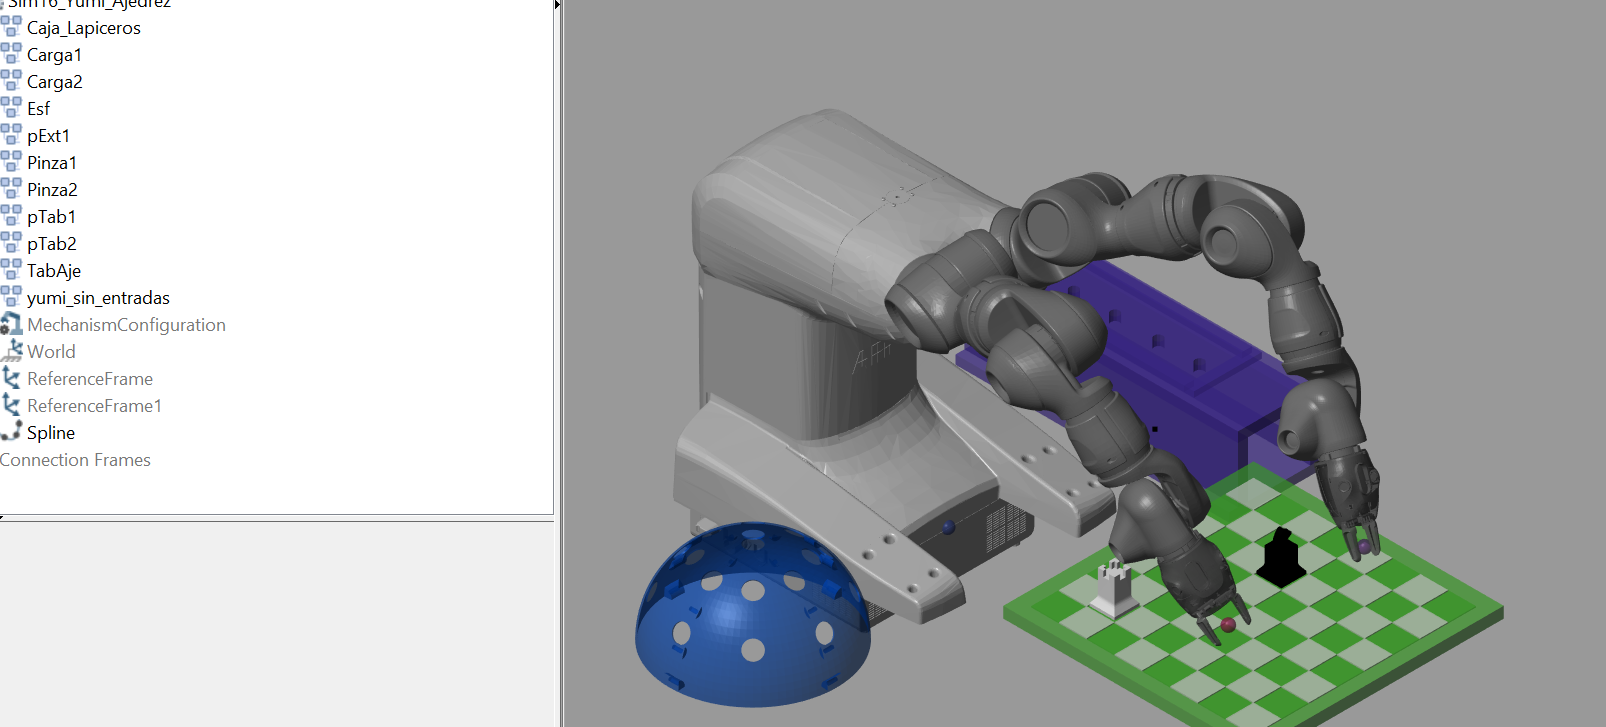

## Cinemática inversa por incremento Jacobiano

% Se puede probar
rob.JacIK(0.6)

ans = 'Body11'

J1 =    -0.0903   -0.2412   -0.0903   -0.3205    0.0000   -0.1122    0.0000         0         0         0         0         0         0         0
    0.4269   -0.2211    0.4269   -0.1513    0.0000   -0.0582    0.0000         0         0         0         0         0         0         0
   -0.1544   -0.4703   -0.1544   -0.2309   -0.0000   -0.0954   -0.0000         0         0         0         0         0         0         0
    0.4698   -0.3336    0.4698   -0.3336   -0.8173   -0.3336   -0.8173         0         0         0         0         0         0         0
    0.3420    0.9223    0.3420    0.9223   -0.1799    0.9223   -0.1799         0         0         0         0         0         0         0
    0.8138   -0.1950    0.8138   -0.1950    0.5474   -0.1950    0.5474         0         0         0         0         0         0         0


## Jacobiano de robot dependiendo del TCP

- El jacobiano obtenido con una herramienta es cero en la mitad de las articulaciones del robot

- Lo mismo pasa al usar la otra herramienta.

- La matriz jacobiana no es cuadrada, por lo que hay que usar la pseudo-inversa.


rob.Tool(TcpCarga1)

ans = 'Body21'


J1= rob.Jac

J2 =          0         0         0         0         0         0         0    0.0893   -0.2410    0.0893   -0.3204   -0.0000   -0.1121   -0.0000
         0         0         0         0         0         0         0    0.4266    0.2222    0.4266    0.1515   -0.0000    0.0583   -0.0000
         0         0         0         0         0         0         0    0.1560   -0.4699    0.1560   -0.2309   -0.0000   -0.0953   -0.0000
         0         0         0         0         0         0         0    0.4698    0.3370    0.4698    0.3370   -0.8159    0.3370   -0.8159
         0         0         0         0         0         0         0   -0.3421    0.9215   -0.3421    0.9215    0.1836    0.9215    0.1836
         0         0         0         0         0         0         0    0.8138    0.1929    0.8138    0.1929    0.5483    0.1929    0.5483



rob.Tool(TcpCarga2)

J2= rob.Jac


ans = 'Body10'

ans =     0.6260    0.1233    0.2208    1.7791    0.3402    2.6199


ans = 'Body20'

ans =     0.6264   -0.1217    0.2215    1.3645   -0.3437    2.6191


## Objetivo de movimiento

- El fijar una herramienta implica que se va a mover el robot correspondiente a esa herramienta.

- El objetivo de la cinemática inversa es mover esa herramienta a un punto determinado, y para ello hay que mover los brazos del robot asociado a la herramienta.

rob.Tool(TcpPinza1)
rob.Pose
rob.Tool(TcpPinza2)
rob.Pose


## Cinemática directa

- Movemos el eje 5 o 11, es decir, el eje 5 del primer robot o el 5 del segundo.

eje= zeros(1,14);
%eje(11)= 90*deg;
rob.MoveAbsJ(eje);


## Movimientos con los dos robots

- Movemos los dos robots a un mismo punto.

- Primero se fija como herramienta el bodyCarga1 y luego el bodyCarga2.

deg= pi/180;
eje= zeros(1,14);
eje([1,8])= [30,-30]*deg;
rob.MoveAbsJ(eje);


punto= [[0, 0, 50]*1e-3, [0, 0, 180]*deg];
rob.Tool(TcpPinza1);


rob.MoveJ(punto, Prod(TabAje, pTab1), 50);
